### Optional Parameters (Before Running)

% Set to true to saves all original faces as .pngs in directory ./Original_Faces/
saveOriginals = false 

% Set this to true to create and save a video of all the original faces
createVideo = false; 

### Task 3: Mean face and eigenfaces

Implement code in MATLAB to produce the mean face and eigenfaces figures from the Background Reading document.

#### Data Preprocessing

% Extracting face data to matrix representation
clear
cd 'C:\Users\liamf\OneDrive\QUT\2021\Sem 1\MXB201\Group Project'
path = 'MXB201_2021_Project_data/faces/';
d = dir(strcat(path, '*.pgm'));
faces = []; % Initialising matrix for faces
for j = 1:length(d)
    I = imread([path, d(j).name]);
    faces(:, :, j) = I; % Adding face to matrix
end

% Image Constants
imgWidth = numel(faces(1, :, 1));
imgHeight = numel(faces(:, 1, 1));
imgCount = numel(faces(1, 1, :));

#### Saving original faces as .pngs

% Saves all original faces as .pngs in directory ./Original_Faces/
if saveOriginals
    mkdir './Original_Faces/'
    for i = 1:imgCount
        imwrite(mat2gray(faces(:, :, i)), fullfile('./Original_Faces/', append('face', int2str(i), '.png')));
    end
end

#### Converting faces from matrix representation to column representation

% Reshaping images to column representation
A = zeros(imgHeight * imgWidth, imgCount);
for i = 1:imgCount % for all faces
    for j = 1:imgWidth % for all columns in face
        A(((imgHeight * (j-1)) + 1):(imgHeight * j), i) = faces(:, j, i);
    end
end

#### Mean Face (Column representation)

% The mean face in column representation
meanFaceCol = zeros(imgHeight * imgWidth, 1);
for i = 1:length(A(:, 1, 1))
    meanFaceCol(i, 1) = mean(A(i, :, :));
end

#### Mean Face (Matrix representation)

% The mean face in matrix representation
meanFace = zeros(imgHeight, imgWidth);
for i = 1:length(meanFaceCol(:, 1)) / imgHeight
    meanFace(:, i) = meanFaceCol((imgHeight * (i-1)) + 1:(imgHeight * i), 1);
end

#### Mean Face

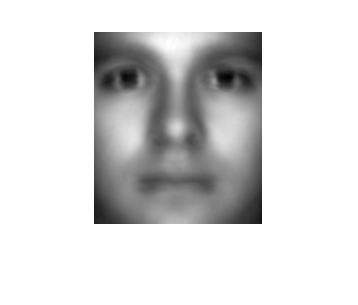

imshow(mat2gray(meanFace)) % Display the Mean Face

% Saving the Mean Face as a .png
imwrite(mat2gray(meanFace),  'meanface.png');

#### Mean Centring

% This will be referred to as the Mean Centred matrix
meanCentred = A - meanFaceCol; 

#### Eigenfaces (Reduced Singular Value Decomposition)

% Identifying the leading eigenvalues using Reduced SVD
[U, Sigma, V] = svd(meanCentred, 'econ')

U =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049   -0.0004   -0.0082    0.0075   -0.0013   -0.0003    0.0060    0.0014    0.0019    0.0111   -0.0007   -0.0008   -0.0043    0.0087    0.0000   -0.0061    0.0079    0.0051    0.0015   -0.0017    0.0079    0.0058   -0.0012    0.0107    0.0082    0.0010   -0.0022   -0.0019   -0.0090   -0.0008    0.0035
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056   -0.0006   -0.0078    0.0066   -0.0016    0.0003    0.0049    0.0016    0.0009    0.0117   -0.0015   -0.0006   -0.0033    0.0079   -0.0007   -0.0053    0.0081    0.0041    0.0011   -0.0014    0.0081    0.0044   -0.0012    0.0104    0.0074    0.0008   -0.0007   -0.0012   -0.0112   -0.0013    0

Sigma = 	1.0e+05 *

    1.4981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

V =    -0.0087   -0.0214    0.0011   -0.0223    0.0024   -0.0094    0.0142    0.0088   -0.0064    0.0314   -0.0194    0.0301   -0.0155    0.0448   -0.0067    0.0646   -0.0084    0.0029    0.0146   -0.0214    0.0652   -0.0336    0.0181   -0.0004    0.0173   -0.0217    0.0065   -0.0371    0.0130   -0.0098    0.0131   -0.0082    0.0287   -0.0071    0.0108   -0.0073    0.0195    0.0602   -0.0282    0.0090   -0.0286   -0.0045    0.0272    0.0057    0.0194   -0.0164    0.0036    0.0077    0.0084    0.0037
   -0.0115   -0.0273   -0.0359   -0.0185    0.0066   -0.0085    0.0048    0.0066   -0.0342    0.0259   -0.0183    0.0353   -0.0051    0.0365    0.0047    0.0559   -0.0265    0.0015    0.0072   -0.0085    0.0952   -0.0342    0.0239    0.0396    0.0230   -0.0092    0.0222   -0.0401    0.0105   -0.0245   -0.0140   -0.0307    0.0168   -0.0464   -0.0068   -0.0286    0.0089    0.0536   -0.0243    0.0103   -0.0305    0.0021    0.0194   -0.0032    0.0101    0.0001    0.0169   -0.0045   -0.0108    0

sigma = diag(Sigma)

sigma = 	1.0e+05 *

    1.4981
    1.3162
    0.8023
    0.5178
    0.4554
    0.4080
    0.3869
    0.3534
    0.2989
    0.2900


#### The first 20 leading eigenfaces

% Producing the 20 leading eigenfaces as seen in the background document
numEigenfaces = 20;

eigenfaces = zeros(imgHeight, imgWidth, numEigenfaces); 
for i = 1:numEigenfaces % For all 20 eigenfaces
    for j = 1:length(U(:, i)) / imgHeight 
        eigenfaces(:, j, i) = U((imgHeight * (j-1)) + 1:(imgHeight * j), i); % Convert from column to matrix representation
    end
end

#### Saving the first x leading eigenfaces as .pngs

% Saving the reconstructed faces as .pngs to directory ./Leading_Eigenfaces/
mkdir './Leading_Eigenfaces/'

for i = 1:numEigenfaces
    imwrite(mat2gray(eigenfaces(:, :, i)), fullfile('./Leading_Eigenfaces/', append(int2str(i), '.png')));
end

### Task 4: Eigenface count vs. accuracy

... make a convincing argument supported by the data that only a relatively small number $v<<1000$ of eigenfaces are required to reconstruct faces to high visual accuracy ...

    (The argument above will be in the report, not here.)

Support your argument with code that demonstrates the process working:

#### The relative decay in magnitude for singular values

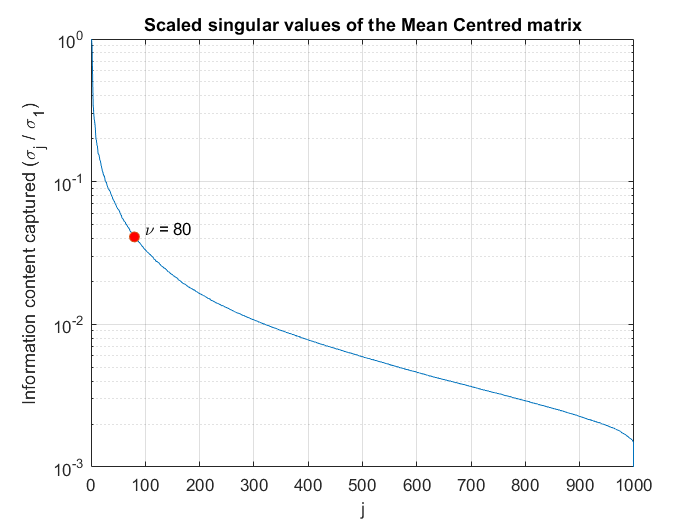

% Create plot demonstrating no. leading eigenvalues vs. quality of
% reconstruction
figure
semilogy(sigma / sigma(1))
hold on
plot(80, sigma(80) / sigma(1), 'o', 'MarkerFaceColor','r')
text(100, sigma(70) / sigma(1), "\nu = 80")
hold off
grid on
xlabel('j')
ylabel('Information content captured (\sigma_j / \sigma_1)')
title('Scaled singular values of the Mean Centred matrix')
ylim([10^(-3) 10^0])

#### Reconstructing the first 3 faces using desired $\nu \;$value

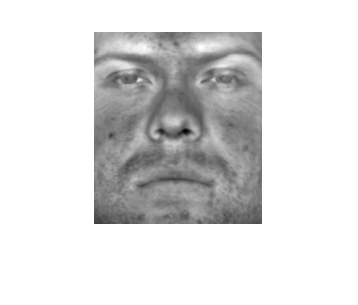

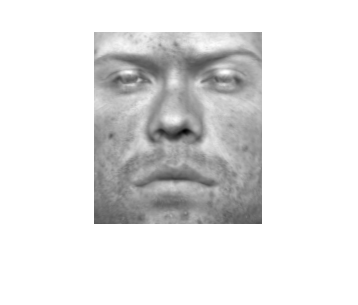

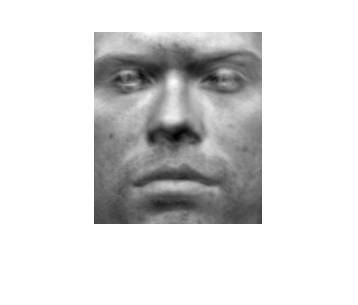

nu = 80;  % Using the first 80 singular vectors
numRecontructions = 3; % Reconstruct the first 3 faces
CV = zeros(nu, numRecontructions); % Will be matrix of coordinate vectors e.g. CV(:, 1) = c1
for i=1:numRecontructions
    CV(:, i) = Sigma(1:nu, 1:nu) * V(i, 1:nu)'; % coordinate vector of meanCentered(:,i)
end

% Create reconstructed columns from U
reconstructedFacesCols = zeros(imgHeight * imgWidth, numRecontructions);
for i=1:numRecontructions
    reconstructedFacesCols(:, i) = U(:, 1:nu)*CV(:, i); % reconstructedFaceCol = U(:, 1:nu)*CV(:, i)
end

% Convert column representation to matrix representation for each
% reconstruction
reconstructedFaces = zeros(imgHeight, imgWidth, numRecontructions);
for i = 1:numel(reconstructedFaces(1, 1, :))
    for j = 1:length(reconstructedFacesCols(:, i)) / imgHeight
        reconstructedFaces(:, j, i) = reconstructedFacesCols((imgHeight * (j-1)) + 1:(imgHeight * j), i);
    end
    figure
    imshow(mat2gray(reconstructedFaces(:, :, i))); % Show reconstructed faces in MATLAB
end

#### Saving the 3 reconstructed faces as .pngs

% Saving the reconstructed faces as .pngs to directory ./Reconstructed_Faces/
mkdir './Reconstructed_Faces/'

for i = 1:numRecontructions
    imwrite(mat2gray(reconstructedFaces(:, :, i)), fullfile('./Reconstructed_Faces/', append('reconstructed_nu-', int2str(nu), '_', int2str(i), '.png')));
end

### Misc: Creating a video of the original faces

% Convert faces to video 
if createVideo
    writerObj = VideoWriter('faces.avi');
    writerObj.FrameRate = 30;
    open(writerObj);
     
    for i = 1:length(d)
        frame = faces(:, :, i);
        frame = mat2gray(frame);
        writeVideo(writerObj, frame);
    end
     
    close(writerObj);
end